# Point Spread Function (PSF) Demo

clear all
close all
clc

Consider a 2D camera that takes input signal, $s_\mathrm{i}(x,y)$, and produces an output image, $s_\mathrm{o}(x,y)$. The camera point spread function (i.e., impulse response) is $h(x,y)$.

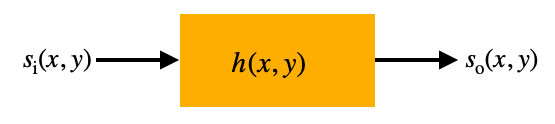

If we can assume the camera acts as a linear and shift invariant system, then we know that 

$s_\mathrm{o}(x,y) =s_\mathrm{i}(x,y) \ast h(x,y)$, where '$\ast$' indicates convolution.  

Let the chess queen image serves as our input signal. (Of course, in reality, this would be a continuous function, but for the sake of demonstrating the concept of a PSF, we'll just skip the issue of sampling for the moment.)

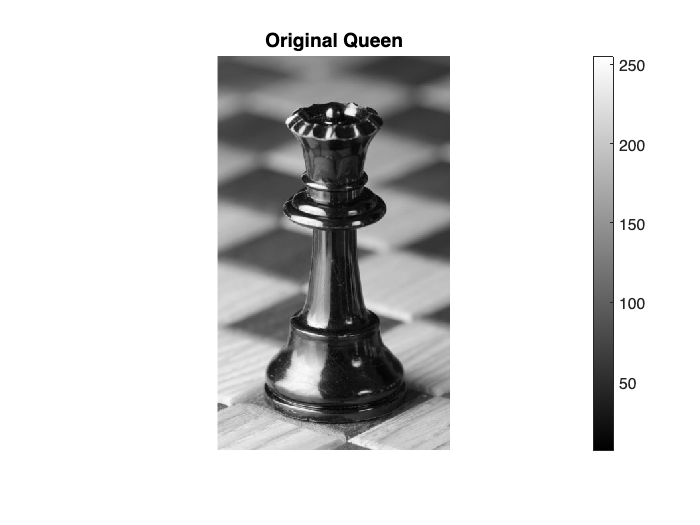

IMG = rgb2gray(imread('Chess_piece.jpg'));
% read in the jpeg file, then convert the RGB signal to a grayscale image
imagesc(IMG)
axis('equal'), colormap(gray), colorbar, axis('off') % present image
title('Original Queen')

[Nr,Nc] = size(IMG);
fprintf('The image size is %d x %d \n', Nr,Nc);

The image size is 594 x 350 


#### The PSF

Let's define the PSF, $h(x,y)$ to have a size in each direction ( $N$ ) as one-tenth the size of the image in the smallest dimension. Also, let's force $N$ to be odd.

N = floor(min([Nr,Nc]/10));
if ~logical(mod(N,2))
    N = N+1;
end
fprintf('The PSF size is %d x %d \n', N,N);

The PSF size is 35 x 35 


For this, MATLAB has a number of built-in shapes that are commonly used to smooth data, which is typically what a PSF is doing. Look up the `window` function. 

help window

 window Window function gateway.
    window(@WNAME,N) returns an N-point window of type specified
    by the function handle @WNAME in a column vector.  @WNAME can
    be any valid window function name, for example:
 
    @bartlett       - Bartlett window.
    @barthannwin    - Modified Bartlett-Hanning window. 
    @blackman       - Blackman window.
    @blackmanharris - Minimum 4-term Blackman-Harris window.
    @bohmanwin      - Bohman window.
    @chebwin        - Chebyshev window.
    @flattopwin     - Flat Top window.
    @gausswin       - Gaussian window.
    @hamming        - Hamming window.
    @hann           - Hann window.
    @kaiser         - Kaiser window.
    @nuttallwin     - Nuttall defined minimum 4-term Blackman-Harris window.
    @parzenwin      - Parzen (de la Valle-Poussin) window.
    @rectwin        - Rectangular window.
    @taylorwin      - Taylor window.
    @tukeywin       - Tukey window.
    @triang         - Triangular win

Let's try a Gaussian window, with `sig` defining the standard deviation of the gaussian function ... try changing this to different values, below

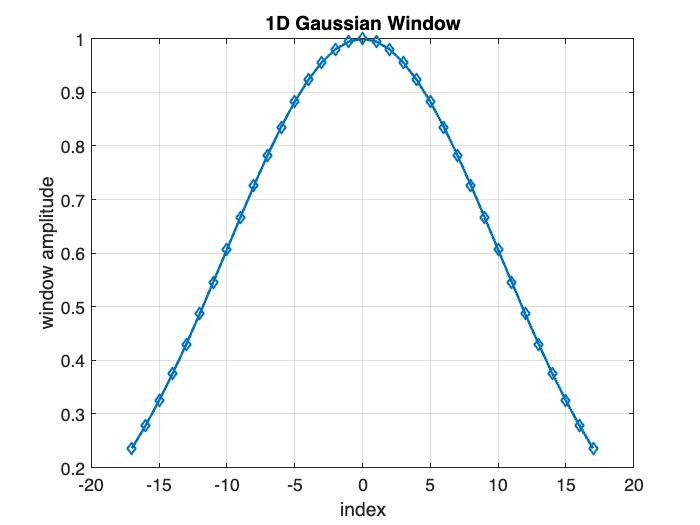

sig = 10; % larger sig will create a wider PSF and more blurring
alpha = (N-1)/(2*sig); % see documentation on gausswin
h1 = window(@gausswin,N,alpha);
hi = -(N-1)/2:1:(N-1)/2;
plot(hi,h1,'d-')
xlabel('index'), ylabel('window amplitude')
title('1D Gaussian Window')

This is a 1D window, but we can make a 2D windown easily using a linear algebra. If the 1D window is a column vector, h1, then a 2D window is 


$$\mathbf{h}_\mathrm{2D} = \mathbf{h}_1\mathbf{h}_1^\mathrm{T}$$


-- recall, (Nx1) x (1xN) = (N x N) matrix

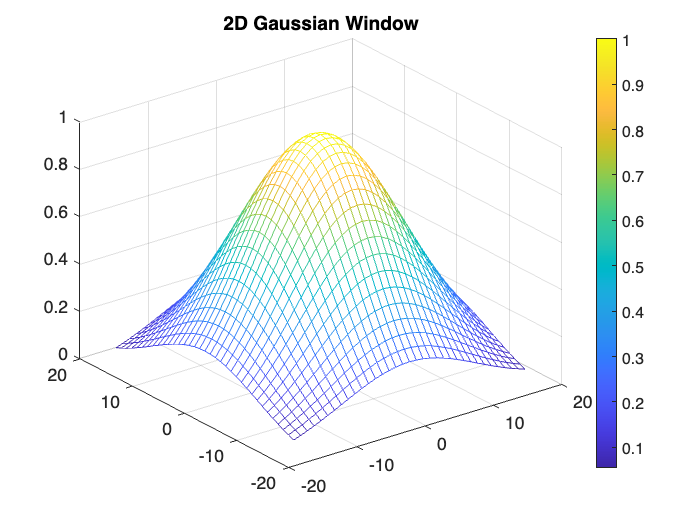

h2D = h1*h1';
mesh(hi,hi',h2D)
colormap(parula), colorbar 
title('2D Gaussian Window')

This looks correct. It's a 2D Gaussian shape with a peak amplitude of 1. Let's use this as a PSF and compute the output of your linear and shift-invariant system. MATLAB has a built-in 2D convolution function. Using the `'same'` option will crop the output to match the size of the first input argument.

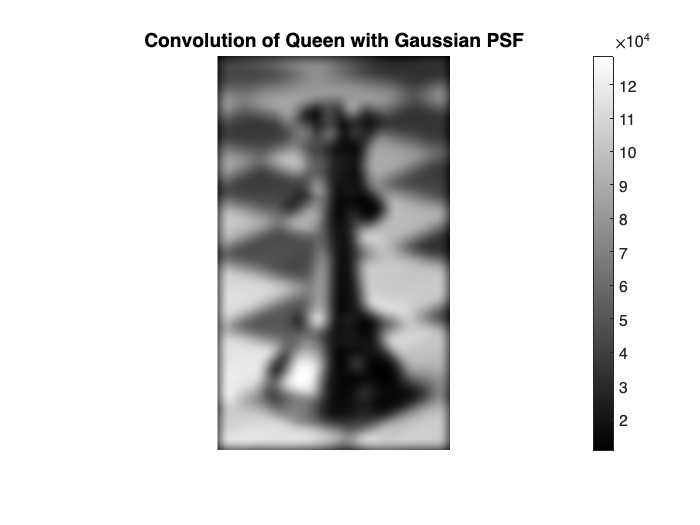

IMG_output = conv2(double(IMG),h2D,'same');
imagesc(IMG_output)
axis('equal'), colormap(gray), colorbar, axis('off')
title('Convolution of Queen with Gaussian PSF')

The image is obviously blurred, which is what we expiected, but if you look at the colorbar you'll see that the intensity of the pixels (i.e., the amplitude of the signal) is way way higher than the original. Take a second to think about why this is?

The reason is that a PSF (or, for that matter, a 1-D impulse reponse) should not have a peak amplitude of 1 but should integrate to 1. This is true for a Gaussian function in general, but the window function by default scales functions to a peak amplitude of 1. To scale h2D appropriately, note that `conv` and `conv2` functions in MATLAB do not actually integrate, the just sum. Thus, the sum of amplitudes across all elements of the PSF should equal 1.

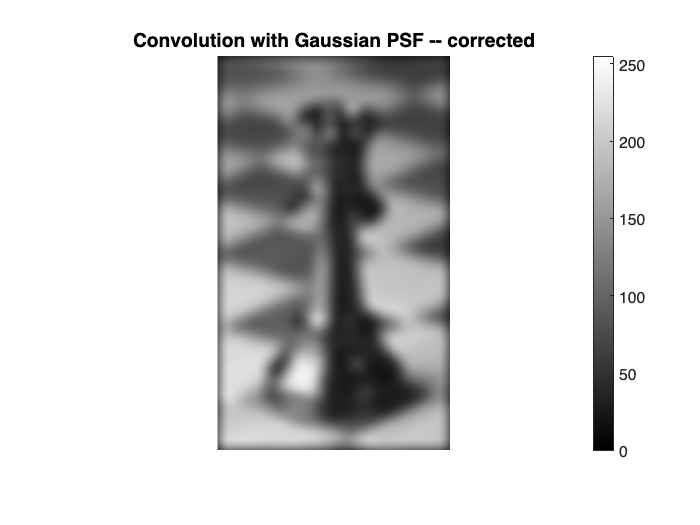

h2D = h2D./sum(h2D(:)); % scale the PSF 

IMG_output = conv2(double(IMG),h2D,'same');
imagesc(IMG_output,[0 255])
axis('equal'), colormap(gray), colorbar, axis('off')
title('Convolution with Gaussian PSF -- corrected')

Now we see what we were expecting---a blurred image, without scaling of the overall signal amplitude. 

To get a better feel for how the PSF affects the image, go back and re-run this with different PSFs. You can start by trying different options from the `window` function, but you'll find the results look quite similar in that they all blur the orinal image. Instead, try creating a PSF that highlights edges, or sharpends the image.

### Additional Thoughts

Consider that if $h(x,y)$ is an 2D delta function, the output image is a perfect reproduction of the original. And, if $h(x,y)$ is a 2D gausssian, the image is blurred. So, if $h(x,y)$ is the *difference* between a delta and a gaussian, then the output will be the *diffference* between the original and smoothed image.

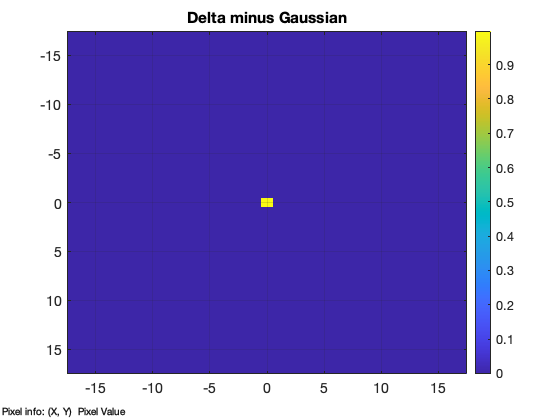

hdelta = zeros(size(h2D));
hdelta((end+1)/2,(end+1)/2) = 1;
hdiff = hdelta-h2D;

imagesc(hi,hi',hdiff)
colormap(parula), colorbar 
title('Delta minus Gaussian')

Note that this impulse response function looks very close to a delta, because the amplitude of the gaussian function is relatively small. If you look closely, you'll see that the elements of `hdiff` are all negative, except the center point. 

Now let's see what an output image look like from a system with `hdiff` as the impulse reponse.

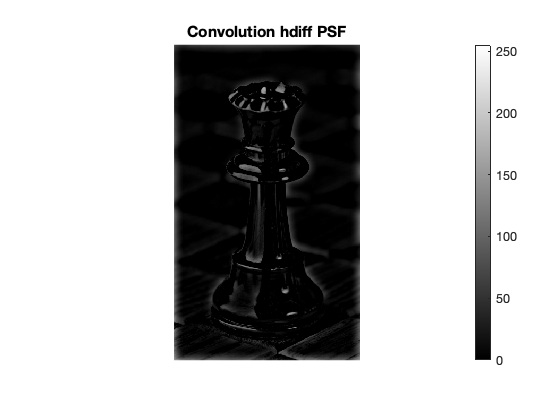

IMG_output = conv2(double(IMG),hdiff,'same');
imagesc(IMG_output,[0 255])
axis('equal'), colormap(gray), colorbar, axis('off')
title('Convolution hdiff PSF')

Now the output image shows the edges and sharp features that were lost by the blurring imparted by the gaussian filter.

### In Class Problem

Create your own 2D impulse response. Make your own impulse response, 35 x 35 pixels in size. 

You can create a symmeric, non-negative 2D impulse response by starting with a 1D column vector, `h1`, and then create a 2D impulse response as `h1*h1'`, as we did above. Or, you can create a 2D matrix of zeros and then set individual elements to particular values.  

Create an image of your impulse response and an image of your output image. Do the results make sense?

For example

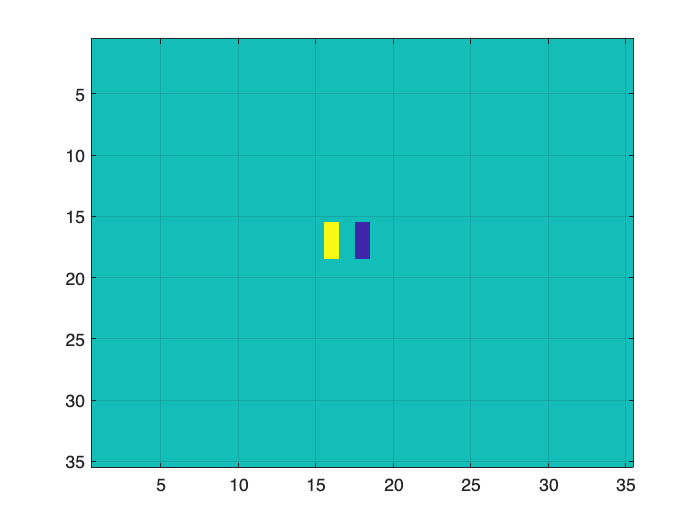

h2Db = zeros(N,N);
ix = int16((N-1)/2);
h2Db(ix-1:ix+1,ix-1:ix+1) = [1 0 -1; 1 0 -1; 1 0 -1];
figure
imagesc(h2Db)

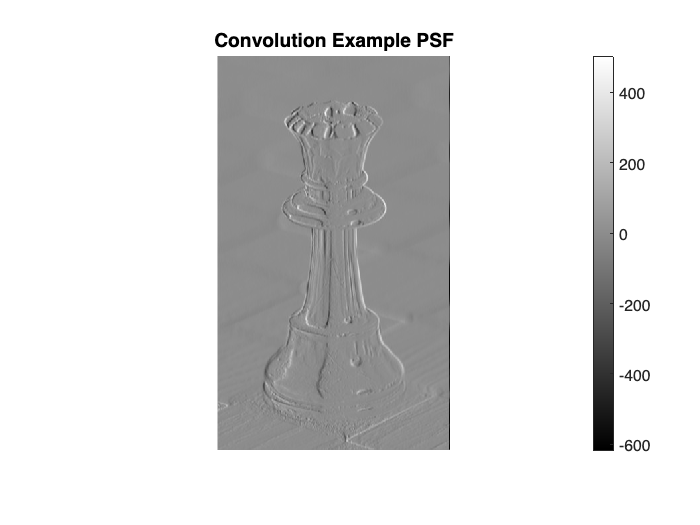

IMG_output = conv2(double(IMG),h2Db,'same');
figure
imagesc(IMG_output)
axis('equal'), colormap(gray), colorbar, axis('off')
title('Convolution Example PSF')

Here we are computing a 2 point central difference approximation of the image derivative in the x-direction.

Cover the Fourier material and then come back for this final section

### The Modulation Transfer Function

One important property of the Fourier Transform is that multiplication in the spatial (or time) domain corresponds to convolution in the frequency domain, and vice versa.

That is, if $S_1(f) = \mathcal{F}\{s_1(t)\}$, where $\mathcal{F}$ indicates Fourier T

ransform, and $S_2(f) = \mathcal{F}\{s_2(t)\}$, then


$$\mathcal{F}\{s_1(t)s_2(t)\} = S_1(f)\ast S_2(f)$$


and


$$\mathcal{F}\{s_1(t) \ast s_2(t)\} = S_1(f) S_2(f)$$


Therefore, for a linear and time/shift-invariant system, like we've discussed above, $S_o(f_x,f_y) = S_i(f_x,f_y)H(f_x,f_y)$.

Here, $H(f_x,f_y) = \mathcal{F}\{h(x,y)\}$is known as the modulation transfer function

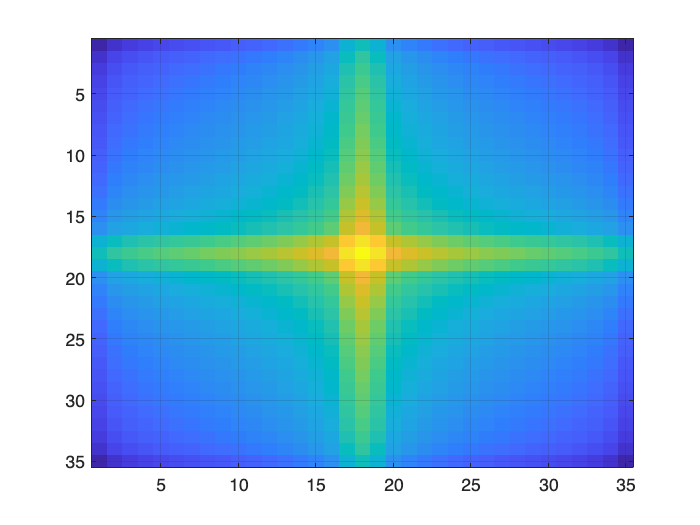

figure
imagesc(log10(abs(fftshift(fft2(h2D)))))